TW = 1.45; %Track Width in m
TW = TW*1000;

Wheel_Diameter = 22; %Wheel Diameter in inch
R = (Wheel_Diameter/2)* 25.4;

Wheel2KnuckleCen = 100; %Distance in mm

Scrub_Radius = 70; %Scrub Radius in mm

Castor = 4; %Castor in degrees

Knuckle_Length_Upper = 60; %Length of Knuckle HP above Knuckle Center
Knuckle_Length_Lower = 50; %Length of Knuckle HP below Knuckle Center

Spindle_Centre = [((-1*TW*0.5)+Wheel2KnuckleCen),0,R/2];
Wheel_Centre = [((-1*TW*0.5)),0,R/2];

Ground_SA = [((-1*TW*0.5)+Scrub_Radius),0,0];

SA_Dir = Spindle_Centre-Ground_SA;
SA_Dir(2) = SA_Dir(3) * tand(Castor);
SA_Dir = unit_vector(SA_Dir)

SA_Dir =     0.2095    0.0682    0.9754



Ground_clearance = 310; %%
A_arm_long_dist = 150; %%

Strut_Height_In = 330;

Nose_width = 470;

c3 = [-1*Nose_width*0.50 -1*A_arm_long_dist, Ground_clearance]

c3 =   -235  -150   310


c4 = [-1*Nose_width*0.5, A_arm_long_dist, Ground_clearance];
c1 = [-1*Nose_width*0.5, -1*A_arm_long_dist, Ground_clearance + (Knuckle_Length_Upper + Knuckle_Length_Lower)*cosd(Castor)];
c2 = [-1*Nose_width*0.5, A_arm_long_dist, Ground_clearance + (Knuckle_Length_Upper + Knuckle_Length_Lower)*cosd(Castor)];
s1 = [-1*Nose_width*0.5, 0, Ground_clearance + Strut_Height_In]

s1 =   -235     0   640


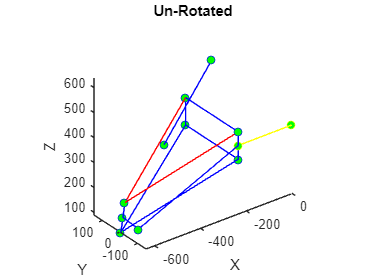


KnuckleHP=[ SA_Dir*Knuckle_Length_Upper+Spindle_Centre ; -1*SA_Dir*Knuckle_Length_Lower+Spindle_Centre];
s2 = [c1(1)+c2(1)+1.4*KnuckleHP(1,1),c1(2)+c2(2)+1.4*KnuckleHP(1,2),c1(3)+c2(3)+1.4*KnuckleHP(1,3)]/3;

StrutIn = [s1;s2];


ChassiHP=[c1;c2;c3;c4];

TieRodIn=[(c1+c3)/2; Spindle_Centre - [0,90,0]];

Plot_Suspension(ChassiHP,KnuckleHP,StrutIn,TieRodIn,'Un-Rotated','blue')
axis equal

[camber,Toe,Castor,KingPIN,StrutLEN,LowerArmAngle,MotionRatioo] = Front_Susp_Parameters(ChassiHP,StrutIn,KnuckleHP,TieRodIn,[-100,100])

camber =    -4.7598         0    1.6249


Toe =    -1.3155    0.0000    0.7447


Castor =    -4.0847   -4.0000   -3.9781


KingPIN =    10.5482   12.1200   16.7913


StrutLEN =   381.7998  404.2562  422.6727


LowerArmAngle =    15.1974   28.6801   43.9552


MotionRatioo =     0.2044    0.2044    0.2044


T=array2table([1,ChassiHP(1,:),ChassiHP(2,:),ChassiHP(3,:),ChassiHP(4,:),StrutIn(1,:),StrutIn(2,:),KnuckleHP(1,:),KnuckleHP(2,:),TieRodIn(1,:),TieRodIn(2,:),-100,100,0])

T = 1×34 table
    Var1    Var2    Var3     Var4     Var5    Var6     Var7     Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16     Var17     Var18     Var19      Var20     Var21     Var22      Var23      Var24     Var25     Var26    Var27    Var28     Var29    Var30    Var31    Var32    Var33    Var34
    ____    ____    ____    ____

output = Parametric_Output_FUNCTION(T)

output =    -4.7598         0    1.6249   -1.3155    0.0000    0.7447   -4.0847   -4.0000   -3.9781   10.5482   12.1200   16.7913  381.7998  404.2562  422.6727   15.1974   28.6801   43.9552    0.1632    0.2042    0.2404
